close all
clear 

Wrocław 20.06.2021

Aleksander Kudyba   

245084

# Wyznaczanie zależności wydajności ogniwa fotowoltaicznego od oporności upływu oraz oprności szeregowej w modelu dwudiodowym.

Model dwudiodowy stusuje się w celu przybliżenia charakterystyki prądowo - napięciowej rzeczywistego ogniwa słonecznego. Za pomocą tego medelu można zbadać wpływ oprności szeregowej i upływu na charakterystykę I-V ogniwa, a co za tym idzie ich wpływu na wydajność. Możemy więc w przypadku, kiedy dysponujemy eksperymentalnie wyznaczonymi dwiema oprnościami łatwo wyznaczyć wydajność, bez dalszych badań eksperymentalnych. Do wyznaczania wydajności zastosowano standard AM1.5, stąd moc wejściowa $P_{in}$ ma wartość 1000 $kW/m^2$, a temperatura 25 $^{\circ}C$; 298.15 $K$.

Wzór modelu dwudiodowego:


$$I = I_L - I_{01}*exp\left(\frac{q(U + IR_s)}{kT}\right) -  I_{02}*exp\left(\frac{q(U + IR_s)}{2kT}\right) - \frac{U+IR_s}{R_{sh}}$$


Współczynnik wypełninia:


$$FF = \frac{V_{mp}I_{mp}}{V_{oc}I_{sc}}$$


Wydajność ogniwa: 


$$\eta = \frac{V_{oc}I_{sc}FF}{P_{in}}$$


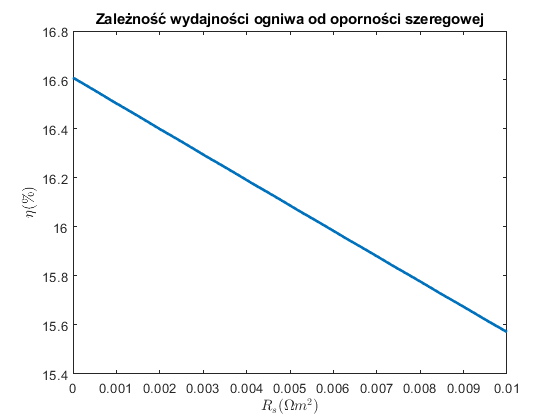

A = 0.01; % m^2
I_l =3.5 ;% A
I_01 =  "1e-10";% A
I_01 = str2num(I_01);
I_02 = "1e-5"; % A  
I_02 = str2num(I_02);
q = 1.602e-19; % C 
k = 8.617e-5; % ev/K 
k1 = 1.381e-23; % J/K
T = 298.15;
Pin = 1000*A; % W/m^2

%początkowe I z I_l

%Rsh = inf jak Rs zmienne 
%i Rs do zera jak Rsh zmienne
% I(i+1) = I_l - I_01*exp(q*(U + I(i)*Rs)/(k*T)) - I_02*exp(q*(U +
% I(i)*Rs)/(2*k*T)) - (U+I(i)*Rs)/Rsh

flag = false;

if flag == 0
    Rsh = 1e29;

U = linspace(-0.5,0.7,400);
I(1)= I_l; 
j=0;
for Rs = 0:0.0001:0.01 
    j = j+1;
for i=1:1:length(U)-1
    I(i+1) = I_l - I_01*exp(q*(U(i+1) + I(i)*Rs)/(k1*T)) - I_02*exp(q*(U(i+1) + I(i)*Rs)/(2*k1*T)) - (U(i+1) + I(i)*Rs)/Rsh;
end

f=fit(U(:),I(:),'smoothingspline');

P = U.*I;
[m, index] = max(P);
Vmp = U(index);
Imp = I(index);
I1 = feval(f,U);

for i=1:1:length(U)-1
    if I1(i) < 0
        Voc(length(U) - i) = U(i);
    end
end

for i=1:1:length(U)-1
    if U(i) > 0
        Isc(length(U) - i) = I1(i);
    end
end

Voc = Voc(end);
Isc = Isc(end);

FF = (Vmp*Imp)/(Voc*Isc);
eta = (Vmp*Imp)/Pin;
eta_percent = eta*100;

Col(j) = eta_percent;
Rs_col(j) = Rs;
end
plot(Rs_col,Col, 'LineWidth', 2)
xlabel('$R_{s}(\Omega m^2)$','Interpreter', 'latex')
ylabel('$\eta(\%) $','Interpreter', 'latex')
title("Zależność wydajności ogniwa od oporności szeregowej")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

elseif flag == 1 
Rs = 1e-23;
U = linspace(-0.5,0.7,400);
I(1)= I_l; 
j=0;

for Rsh = 1e-2:0.05:10 
    j = j+1;

for i=1:1:length(U)-1
    I(i+1) = I_l - I_01*exp(q*(U(i+1) + I(i)*Rs)/(k1*T)) - I_02*exp(q*(U(i+1) + I(i)*Rs)/(2*k1*T)) - (U(i+1) + I(i)*Rs)/Rsh;
end

f=fit(U(:),I(:),'smoothingspline');

P = U.*I;
[m, index] = max(P);
Vmp = U(index);
Imp = I(index);
I1 = feval(f,U);

for i=1:1:length(U)-1
    if I1(i) < 0
        Voc(length(U) - i) = U(i);
    end
end

for i=1:1:length(U)-1
    if U(i) > 0
        Isc(length(U) - i) = I1(i);
    end
end

Voc = Voc(end);
Isc = Isc(end);

FF = (Vmp*Imp)/(Voc*Isc);
eta = (Vmp*Imp)/Pin;
eta_percent = eta*100;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Col(j) = eta_percent;
Rsh_col(j) = Rsh;
end

plot(Rsh_col,Col, 'LineWidth', 2)
xlabel('$R_{sh}(\Omega m^2)$','Interpreter', 'latex')
ylabel('$\eta(\%) $','Interpreter', 'latex')
title("Zależność wydajności ogniwa od oporności uplywu")
end

%plot(U,I1)
%plot(U,P)